clc;
close all;
clear;
load("robot.mat");

Initial cube position: 0,250,55

Intermediate: ???

Final cube position: 0,300,55

### strategy:

pos 0: 0,0,0,0,0,0

#### position 1:    0,250,100                        

pos 1 joint angle : 90, 40, -3.7, 0, -43.4, 0

#### position 2:    0, 250, 55   

pos 2 joint angle : 90, 56.9, -13.2, 0, -36.7, 0

#### ----------------pump on----------------

#### position 3:                           

joint angle: 90, 29.7, -34.4, 0, 0, 0

#### position 4:   0, 300, 55   

joint angle: 90, 69.0, -35.5, 0, -48, 0

#### ----------------pump off----------------

%calculate joint angle
target_points = []


target_points =

     []



%joint angle
joint_angles = [0,   0,  0,  0,  0,  0;
                   90, 50, -3.7, 0, -36.7, 0;
                   90, 56.9, -13.2, 0, -36.7, 0;
                   90, 29.7, -34.4, 0, 0, 0;
                   90, 69.0, -35.5, 0, -48, 0]';
joint_angles = joint_angles*pi/180;
num_joint_angle = size(joint_angles,2);

#### angle transform

homeconfig = homeConfiguration(robot);
for i = 1:num_joint_angle 
    joint_angles(:,i) = homeconfig + joint_angles(:,i);
end
joint_angles

joint_angles =          0    1.5708    1.5708    1.5708    1.5708
   -1.5708   -0.6981   -0.5777   -1.0524   -0.3665
         0   -0.3491   -0.2304   -0.6004   -0.6196
         0         0         0         0         0
    1.5708    0.9303    0.9303    1.5708    0.7330
         0         0         0         0         0


Step = 30;
tip_positions = zeros([Step*num_joint_angle,3]);
total_steps = Step * num_joint_angle;
num_joints = length(homeconfig);

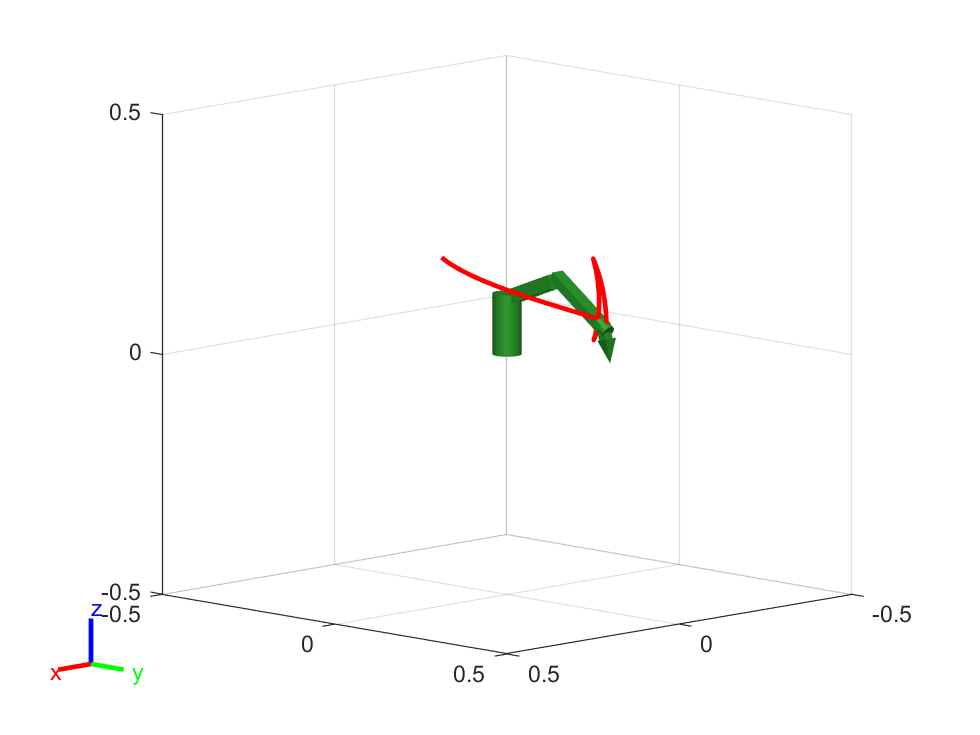

fig = figure('Color', [1 1 1]);
ax = axes('Parent', fig, 'DataAspectRatio', [1 1 1], 'XLim', [-0.5 0.5], 'YLim', [-0.5 0.5], 'ZLim', [-0.5 0.5]);
set(ax, 'XDir','reverse', 'YDir','reverse', 'ZDir','normal');
lighting gouraud;
light('Position',[1 1 1],'Style','infinite');
material dull;  
view(3);
view(ax, -45, 10);
grid on;
hold(ax, 'on');
zoom on;
pan on;
robotPlot = show(robot, joint_angles(:,1), 'Parent', ax, 'PreservePlot', false);
trajectoryPlot = plot3(ax, NaN, NaN, NaN, 'r', 'LineWidth', 2);

v = VideoWriter('Task1.avi');
v.FrameRate = 15;
open(v);
for j = 2:num_joint_angle 
    Qd = joint_angles(:,j)-joint_angles(:,j-1);
    idx = (j-2)*Step;
    for i = 1:Step
        q = joint_angles(:,j-1) + Qd / Step * i;
        tip_positions(i+idx,:) = cal_tip_positions(q);
        show(robot, q, 'Parent', ax, 'PreservePlot', false, "Collisions","on","Frames","off");
        set(trajectoryPlot, 'XData', tip_positions(1:i+idx, 1), 'YData', tip_positions(1:i+idx, 2), 'ZData', tip_positions(1:i+idx, 3));
        drawnow;

        frame = getframe(gcf);
        writeVideo(v, frame);
    end
end
hold(ax, 'off');

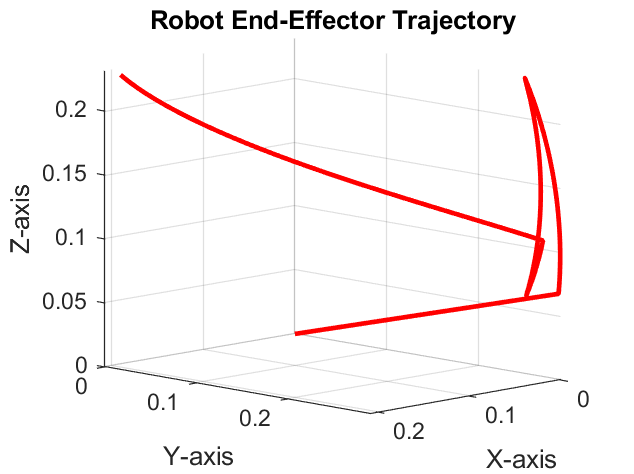

close(v);
figure('Color', [1 1 1]);
plot3(tip_positions(:, 1), tip_positions(:, 2), tip_positions(:, 3), 'r', 'LineWidth', 2);
grid on;
xlabel('X-axis');
ylabel('Y-axis');
zlabel('Z-axis');
title('Robot End-Effector Trajectory');
axis equal;
view(135, 10); 

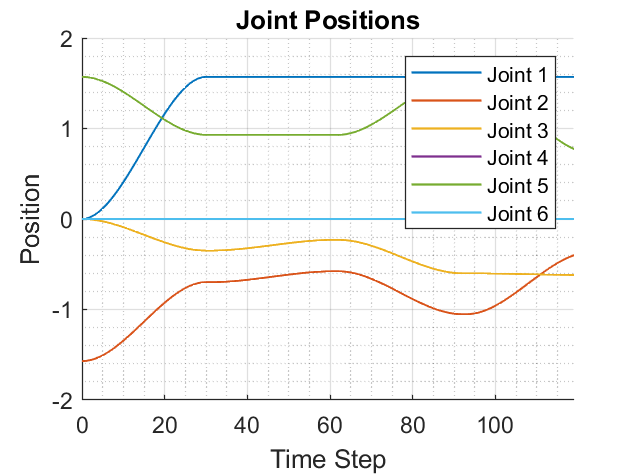

joint_positions = [];
joint_velocities = [];
for i = 1:num_joints
    for j = 2:num_joint_angle 
        [pos, vel] = calculateJointMotion(joint_angles(:,j-1), joint_angles(:,j), Step);
        joint_positions = [joint_positions, pos];
        joint_velocities = [joint_velocities, vel];
    end  
end

t = 0:(size(joint_positions, 2) - 1);
figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_positions(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, (num_joint_angle-1)*Step - 1]);
title("Joint Positions");
xlabel("Time Step");
ylabel("Position");
legend;

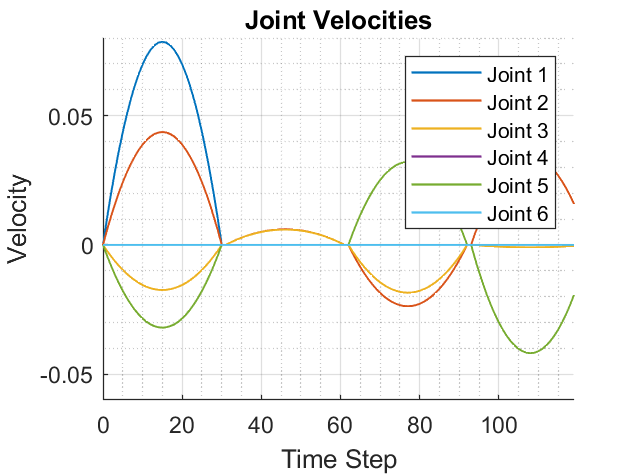


figure('Color', [1 1 1]);
hold on;
grid on;
grid minor;
for i = 1:num_joints
    plot(t, joint_velocities(i,:), 'LineWidth', 1, 'DisplayName', ['Joint ' num2str(i)]);
end
xlim([0, (num_joint_angle-1)*Step - 1]);
title("Joint Velocities");
xlabel("Time Step");
ylabel("Velocity");
legend;